## Concept Check: Introduction to Machine Learning

Q1. Classification / Object detection

Q2. Tune model parameters

Q3. Extract Features

## Concept Check: Introduction to Classification

Q1. SVM

Q2. KNN

Q3. KNN / SVM nonlinear

## Preparing Your Images for Classification

dsConcrete = imageDatastore("../../Data/Concrete","IncludeSubfolders",true,"LabelSource","foldernames");
categories(dsConcrete.Labels)

ans = 2×1 の cell 配列
    {'Negative'}
    {'Positive'}


dsConcrete.Labels = renamecats(dsConcrete.Labels,["No Crack","Crack"]);
[dsTrain,dsTest] = splitEachLabel(dsConcrete,0.8,"randomized");

concreteTable = extractConcreteFeatures1(dsTrain)

concreteTable = 800×4 table
     label        imgName      intensityAvg    intensitySTD
    ________    ___________    ____________    ____________

    No Crack    "00044.jpg"      0.77811         0.023076  
    No Crack    "00171.jpg"      0.82787         0.049307  
    No Crack    "00188.jpg"      0.75051         0.045049  
    No Crack    "00268.jpg"      0.75853          0.05298  
    No Crack    "00272.jpg"      0.78788         0.025274  
    No Crack    "00312.jpg"      0.82332         0.047729  
    No Crack    "00332.jpg"      0.81527         0.027192  
    No Crack    "00422.jpg"      0.77582         0.044448  
    No Crack    "00486.jpg"      0.64485        0.0096845  
    No Crack    "00582.jpg"      0.74048         0.027994  
    No Crack    "00628.jpg"      0.62594           0.0262  
    No Crack    "00697.jpg"      0.59696         0.020347  
    No Crack    "00721.jpg"      0.74237         0.051989  
    No Crack    "00735.jpg"      0.78222         0.021937  
    No Crac


save("concreteIntensityFeatures.mat", "concreteTable","dsTrain","dsTest")

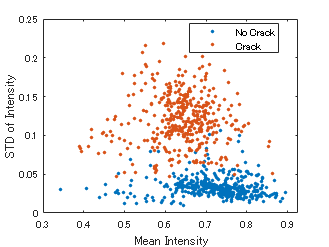

gscatter(concreteTable.intensityAvg,concreteTable.intensitySTD,concreteTable.label)
xlabel("Mean Intensity")
ylabel("STD of Intensity")

## Preparing Your Images for Classification

% fileLocation = uigetdir();
fileLocation = 'C:\Users\kenconnor\Desktop\playground_matlab\Computer Vision for Engineering and Science\Data\Concrete';
dsConcrete = imageDatastore(fileLocation,"IncludeSubfolders",true,"LabelSource","foldernames");
categories(dsConcrete.Labels)

ans = 2×1 の cell 配列
    {'Negative'}
    {'Positive'}


dsConcrete.Labels = renamecats(dsConcrete.Labels,["No Crack","Crack"]);
categories(dsConcrete.Labels)

ans = 2×1 の cell 配列
    {'No Crack'}
    {'Crack'   }


[dsTrain,dsTest] = splitEachLabel(dsConcrete,0.8,"randomized");
countEachLabel(dsTrain)

ans = 2×2 table
     Label      Count
    ________    _____

    No Crack     400 
    Crack        400 


reset(dsTrain)
concreteTable = extractConcreteFeatures2(dsTrain);
save concreteIntensityFeatures.mat concreteTable dsTrain dsTest

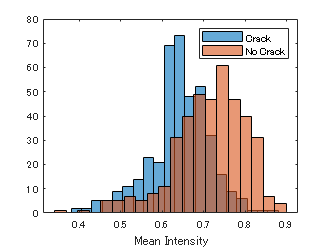

histogram(concreteTable.intensityAvg(concreteTable.label == "Crack"),20)
hold on
histogram(concreteTable.intensityAvg(concreteTable.label == "No Crack"),20)
hold off
xlabel("Mean Intensity")
legend("Crack","No Crack")

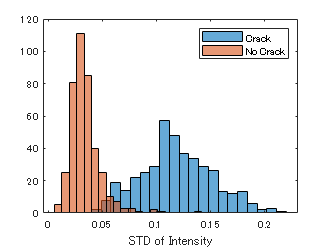


histogram(concreteTable.intensitySTD(concreteTable.label == "Crack"),20)
hold on
histogram(concreteTable.intensitySTD(concreteTable.label == "No Crack"),20)
hold off
xlabel("STD of Intensity")
legend("Crack","No Crack")

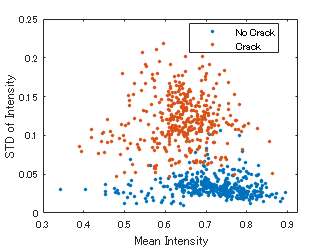


gscatter(concreteTable.intensityAvg,concreteTable.intensitySTD,concreteTable.label)
xlabel("Mean Intensity")
ylabel("STD of Intensity")

## Training Image Classification Models

clear
clc
load concreteIntensityFeatures.mat

% classificationLearner
save concreteCrackClassifier.mat ConcreteCrackClassifier

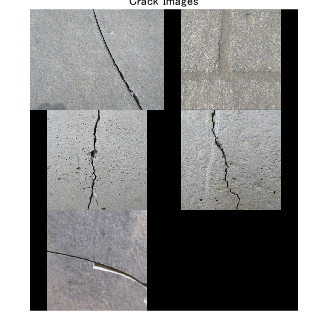

load concreteCrackClassifier.mat
load concreteIntensityFeatures.mat
reset(dsTest)
concreteTableTest = extractConcreteFeatures(dsTest);
dsUnlabeledConcrete = imageDatastore("../../Data/MathWorks Images/Unlabeled Concrete/","LabelSource","foldernames");
concreteTableUnlabeled = extractConcreteFeatures(dsUnlabeledConcrete);
concreteTableUnlabeled.Prediction = ConcreteCrackClassifier.predictFcn(concreteTableUnlabeled);

montage(concreteTableUnlabeled.imgName(concreteTableUnlabeled.Prediction=="Crack"))
title("Crack Images")

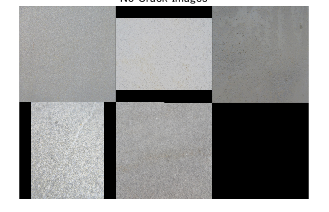

montage(concreteTableUnlabeled.imgName(concreteTableUnlabeled.Prediction=="No Crack"))
title("No Crack Images")

# Assessments: Classifying Images

clear
clc

## Graded Quiz: Preparing Images for Classification

Q1. 85

Q2. saturationAvg = 0.3806

Q3. saturationSTD = 0.2302

Q4. B

## Graded Quiz: Classifying Images

Q1. 14

Q2. 4

Q3. 96.7

Q4. 

% fileLocation = uigetdir()
fileLocation = 'C:\Users\kenconnor\Desktop\playground_matlab\Computer Vision for Engineering and Science\Data\MathWorks Images\Roadside Ground Cover';
dsSnow = imageDatastore(fileLocation,"IncludeSubfolders",true,"LabelSource","foldernames");
categories(dsSnow.Labels)

ans = 2×1 の cell 配列
    {'No Snow'}
    {'Snow'   }


dsSnow.Labels = renamecats(dsSnow.Labels,["Snow","No Snow"],["Snow","No Snow"]);
categories(dsSnow.Labels)

ans = 2×1 の cell 配列
    {'No Snow'}
    {'Snow'   }


[dsTrain,dsTest] = splitEachLabel(dsSnow,0.85,"randomized");
countEachLabel(dsTrain)

ans = 2×2 table
     Label     Count
    _______    _____

    No Snow     85  
    Snow        85  


img = imread("RoadsideA_1.jpg");
imgHSV = rgb2hsv(img);
imgSaturation = imgHSV(:,:,2);
saturationAvg = mean(imgSaturation(:))

saturationAvg = 0.3806

saturationSTD = std(imgSaturation(:))

saturationSTD = 0.2302

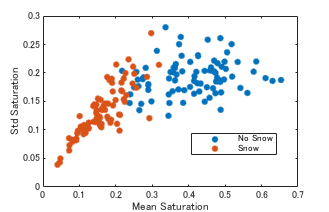

reset(dsTrain)
snowTable = extractSnowFeatures(dsTrain);
gscatter(snowTable.saturationAvg,snowTable.saturationSTD,snowTable.label)
xlabel("Mean Saturation")
ylabel("Std Saturation")

save snowFeatures.mat snowTable dsTrain dsTest

clear
load snowFeatures.mat
reset(dsTest)
snowTableTest = extractSnowFeatures(dsTest);
classificationLearner

save snowClassifier.mat snowClassifier

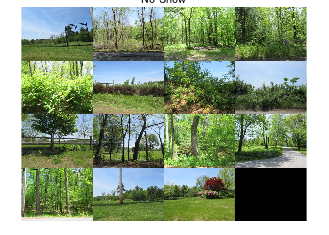

clear
load snowClassifier.mat
load snowFeatures.mat
snowTableTest = extractSnowFeatures(dsTest);
snowTableTest.Prediction = snowClassifier.predictFcn(snowTableTest);
montage(snowTableTest.imgName(snowTableTest.label == "No Snow"))
title("No Snow")

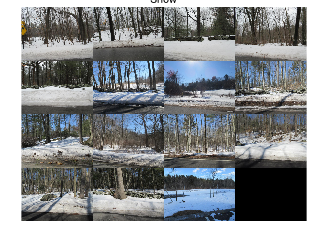

montage(snowTableTest.imgName(snowTableTest.label == "Snow"))
title("Snow")